** Downsampling artefacts & Anharmonic oscillators**

We attempt to determine the size of the effect of a probe beam on the oscillation frequency of a magnetically trapped BEC. We recover fitted frequencies from downsampled data, but observe an amplitude-dependence in the fitted frequency.

In this notebook, I:

- Test the veracity of the frequency-recovery method in the case of a damped sine wave, and find that it recovers the parameters of the oscillator quite well.

- Introduce anharmonic elements to the oscillator potential and examine the resulting fit errors.

First, let's look at the basic pieces of our analysis. Matlab's ode45 is a Runge-Katta integrator that produces the trajectory of a damped harmonic oscillator (with anharmonic terms set to zero).

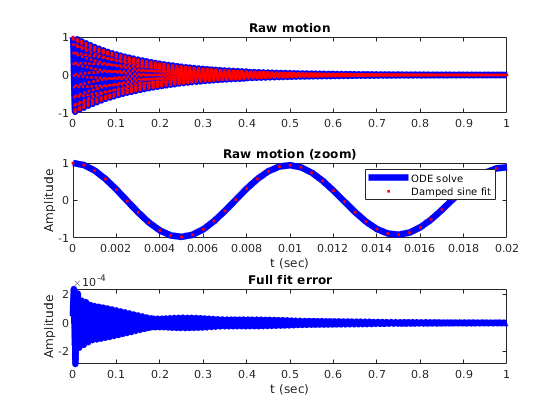

%% Setting up Parameters
X0 = [1 0];
global trap_freq; 
m = 1;
trap_freq = 100.213; %HERTZ
T_win = linspace(0,1,2000);

P = [m m*(2*pi*trap_freq)^2 6 0 0];%[m, spring, damping, cubic, quartic] 
% Input designed to keep trap freq constant; fixes k given m.

fit_coef_names = {'Freq','Phase','Damping rate','Offset'};
%Solve for evolution of nonlinear oscillator

[t,Y] = ode45(@(t,X) trap_DE(t,X,P),T_win,X0);
f1 = figure;
figure(f1);


% Fit full signal
beta0 = [trap_freq, 0,0,0];
full_fit = fitnlm(t,Y(:,1),@damped_sine,beta0,'CoefficientNames',fit_coef_names);
figure(f1);
subplot(3,1,1)
plot(t,Y(:,1),'b','LineWidth',5)
title('Raw motion')
hold on
plot(t,damped_sine(full_fit.Coefficients.Estimate,t),'r.');
subplot(3,1,2)
plot(t,Y(:,1),'b','LineWidth',5)
title('Raw motion (zoom)')
hold on
plot(t,damped_sine(full_fit.Coefficients.Estimate,t),'r.');
xlim([0, 0.02])
legend('ODE solve','Damped sine fit')
xlabel('t (sec)')
ylabel('Amplitude')
subplot(3,1,3)
plot(t,Y(:,1)-damped_sine(full_fit.Coefficients.Estimate,t),'b','LineWidth',5)
title('Full fit error')
xlabel('t (sec)')
ylabel('Amplitude')

full_fit.Coefficients.Estimate

ans =   100.2181
   -1.5805
    6.0214
    0.0000


However, in our experiment we don't have the luxury of sampling faster than the trap oscillations. Therefore the actual oscillations will be aliased down into the zeroth (by convention adopted below) Nyquist zone. The nyquist zone number can be calibrated by dithering the sample frequency and measuring the gradient of the downsampled fit frequency. In this demonstration the trap frequency is fully controllable, so there is a simple calculation to find the Nyquist zone and apparent frequencies. Below, I artificially alias and recover the oscillator frequency and damping coefficient for the motion above.

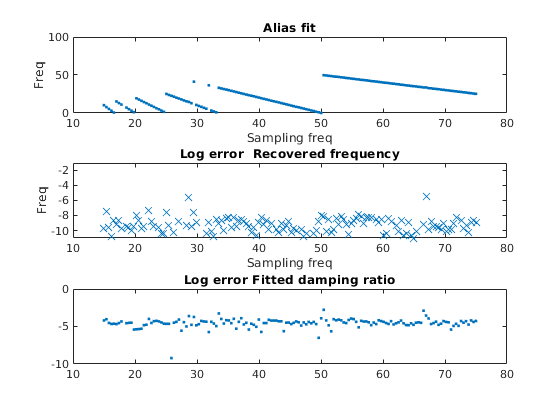

%Reampling: Finding closest times to those given by sample freq
sample_freqs = linspace(15,75,150);
ds_data_demo = cell(numel(sample_freqs),1);
interp = true; %Enable for slightly improved performance
for i=1:numel(sample_freqs)
    warning('off')
    ds_data_demo{i} = resample_fit(Y(:,1),T_win,sample_freqs(i),trap_freq,interp);
    warning('on')
end
figure();
subplot(3,1,1)
plot(sample_freqs,cellfun(@(x) abs(x.ds_fit.Coefficients.Estimate(1)),ds_data_demo)','.')
ylim([-0.01 100])
xlabel('Sampling freq')
ylabel('Freq')
title('Alias fit')
subplot(3,1,2)
plot(sample_freqs,log(abs(cellfun(@(x) x.recon_freq-trap_freq,ds_data_demo))/trap_freq),'x')
hold on
ylim([-11,-1])
% plot([0,max(sample_freqs)],[trap_freq,trap_freq],'r')
title('Log error  Recovered frequency')
xlabel('Sampling freq')
ylabel('Freq')
subplot(3,1,3)
plot(sample_freqs, cellfun(@(x) log(abs(x.ds_fit.Coefficients.Estimate(3)-P(3))/P(3)),ds_data_demo),'.')
ylim([-10,0])
title('Log error Fitted damping ratio')

The resample method seems to do quite well, at least for these trap settings.

In comparison, here is an exact-time sampling (based on the full-fit), which suffers from imperfections in the full fit

%Resampling: Fitting a damped sine and evaluating directly to resample.
sample_freqs = linspace(15,75,150);
rs_data_demo = cell(numel(sample_freqs),1);
jitter = true; %Disable for magic
for i=1:numel(sample_freqs)
    warning('off')
    rs_data_demo{i} = downsample_fit(Y(:,1),t,sample_freqs(i),P,jitter);
    warning('on')
end

Undefined function or variable 'downsample_fit'.

figure();
subplot(3,1,1)
plot(sample_freqs,cellfun(@(x) abs(x.ds_fit.Coefficients.Estimate(1)),rs_data_demo)','.')
ylim([-0.01 100])
xlabel('Sampling freq')
ylabel('Freq')
title('Alias fit')
subplot(3,1,2)
plot(sample_freqs,log((abs(cellfun(@(x) x.recon_freq-trap_freq,rs_data_demo)))/trap_freq),'x')
hold on
ylim([-11,-1])
% plot([0,max(sample_freqs)],[trap_freq,trap_freq],'r')
title('Log error Recovered frequency  ')
xlabel('Sampling freq')
ylabel('Freq')
subplot(3,1,3)
plot(sample_freqs, cellfun(@(x) log(abs(x.ds_fit.Coefficients.Estimate(3)-P(3))/P(3)),rs_data_demo),'.')
ylim([-10,0])
title('Log error Fitted damping ratio')

**Interesting. **

So fitting by downsampling (computing exact samples values from the full fit model) and then fitting those produces much better results than finding the nearest sample times in the ODE solution and fitting those. WAY better. Why? 

Hypotheses: 

- Initial data in good fit is 'too good to be true'

- Perfectly periodic sample times in downsampled fit give advantage

Let's try to break these.

- Adding noise to initial data doesn't even come close to breaking performance. Leads some fits to fail, but the best are still several orders better than the resampled version.

- Adding some jitter to sample times kills performance! Interestingly, damping ratio suffers much more. Let's make these cases a bit closer. The average (absolute) jitter between the sample times and the T_win times (as at present realization) is 0.117ms, variance 6ns. The mean jitter is 1.6e-17s! With a variance of just 140us. I synthetically jitter the sample times in the downsampled case. The frequency error gets about 1000x worse, and the damping ratio about 10^6 worse (logspace), but still miles ahead of the resampled method.

- Adding Bryce's interpolation variant also improves performance, to a comparable degree. Interestingly, there are dips in performance at the end and halfway points of the Nyquist zones... 

Seems like the time jitter is more important. In the end, though, we want to look at cases which we *don't* know how to model. So we can't really rely on the downsampling anyway! We'll need to sample from the ODE. What if we insert the desired sample times into the ODE solver? 

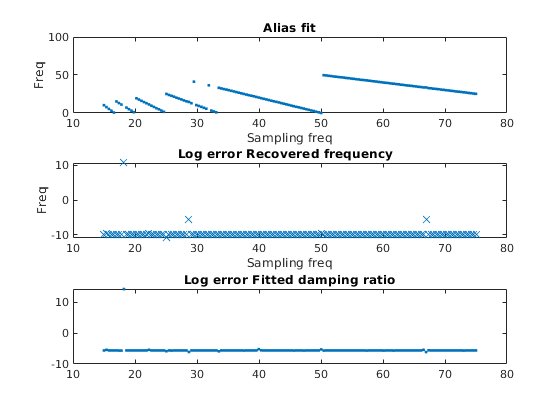

sample_freqs = linspace(15,75,150);
rsi_data_demo = cell(numel(sample_freqs),1);
for i=1:numel(sample_freqs)
    t_samp = [min(T_win),max(T_win)];
    sample_times = t_samp(1):1/sample_freqs(i):t_samp(2);
    T_loc = unique([t;sample_times']);
    [t,Y] = ode45(@(t,X) trap_DE(t,X,P),T_loc,X0);
    warning('off')
    rsi_data_demo{i} = resample_fit(Y(:,1),t,sample_freqs(i),trap_freq);
    warning('on')
end
f2 = figure();
subplot(3,1,1)
plot(sample_freqs,cellfun(@(x) abs(x.ds_fit.Coefficients.Estimate(1)),rsi_data_demo)','.')
ylim([-0.01 100])
xlabel('Sampling freq')
ylabel('Freq')
title('Alias fit')
subplot(3,1,2)
plot(sample_freqs,log((abs(cellfun(@(x) x.recon_freq-trap_freq,rsi_data_demo)))/trap_freq),'x')
hold on
% plot([0,max(sample_freqs)],[trap_freq,trap_freq],'r')
title('Log error Recovered frequency  ')
xlabel('Sampling freq')
ylabel('Freq')
subplot(3,1,3)
plot(sample_freqs, cellfun(@(x) log(abs(x.ds_fit.Coefficients.Estimate(3)-P(3))/P(3)),rsi_data_demo),'.')
title('Log error Fitted damping ratio')

Bang - pushes performance up to the level of the downsampling method. Great! Now, let's finally get to the effects of damping, then get to bending potentials.

% Downsampling versus damping

damping_tests = linspace(1,10,50);
sample_freqs =linspace(10,55,50);
trap_freq = 50.7123; %HERTZ
X0 = [1 0]; 
T_win = linspace(0,2,10000);
P = [1 (2*pi*trap_freq)^2 0 0 0];

resample_eval_data=cell(numel(damping_tests),numel(sample_freqs));
%Pile ALL the times in so re-solving not necessary every time;
for i=1:numel(sample_freqs)
    T_win = unique([T_win , (min(T_win):1/sample_freqs(i):max(T_win))]);
end

Y_all = cell(size(damping_tests));
% count = 1;
for i=1:numel(damping_tests)
    P(3) = damping_tests(i);
    %Solve for evolution of nonlinear oscillator
    [~,y] = ode45(@(t,X) trap_DE(t,X,P),T_win,X0);
    for k=1:numel(sample_freqs)    
        %Resampling
        warning('off')
        downsample_data = resample_fit(y,T_win,sample_freqs(k),trap_freq);
        warning('on')  
        resample_eval_data{i,k}.data = downsample_data; 
        resample_eval_data{i,k}.damp = P(3);
        resample_eval_data{i,k}.samp_freq = sample_freqs(k); 
        Y_all{i} = y;
%         count = count + 1;
    end
end    

f_err = zeros(numel(damping_tests),numel(sample_freqs));
f_s = zeros(numel(damping_tests),numel(sample_freqs));
d_err = zeros(numel(damping_tests),numel(sample_freqs));
d_s = zeros(numel(damping_tests),numel(sample_freqs));
for i=1:numel(damping_tests)
    for j=1:numel(sample_freqs)
        rs_temp = resample_eval_data{i,j};
        f_s(i,j) = rs_temp.samp_freq;
        d_s(i,j) = rs_temp.damp;
        f_err(i,j) = (rs_temp.data.recon_freq-trap_freq)/trap_freq;
        d_err(i,j) = (rs_temp.data.ds_fit.Coefficients.Estimate(3)-d_s(i))/d_s(i);
    end
end

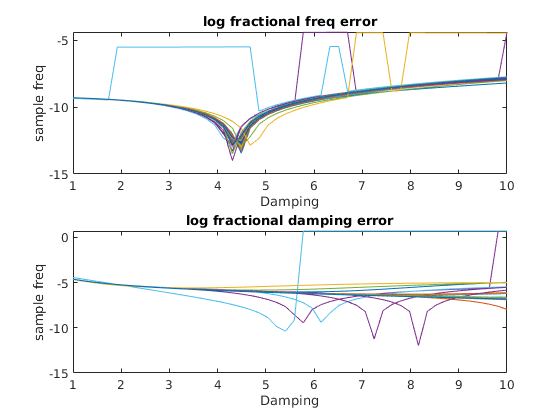

figure()
for i=1:numel(sample_freqs)
    subplot(2,1,1)
    plot(d_s(:,i),log(abs(f_err(:,i))))
    hold on
    title('log fractional freq error')
    xlabel('Damping')
    ylabel('sample freq')
    subplot(2,1,2)
    plot(d_s(:,i),log(abs(d_err(:,i))))
    hold on
    title('log fractional damping error')
    xlabel('Damping')
    ylabel('sample freq')
end

Conclusions: Actually, the downsampling does *extremely well * at reconstructing the fit parameters of a damped sine wave. The occasional failure also does damn well. Fixing the pathological failures is certainly possible, but not really worth the time atm.

Now, there's no obvious reason to suspect that fitting subsegments of the curve would lead to the kind of frequency variance observed in the experiment.

So, moving on!